# Programa de Elementos Finitos para las ecuaciones estacionarias de Navier-Stokes - Estabilización P1P1

h = 0.05;
xmin=-1;
xmax=1;
ymin=-1;
ymax=1;
domain="squareR";
mu= 1;
estabiliza=true;
ejemplo="Cavity";
epsilon=1e-8;

ahora el codigo

[uh,ph,nodos,borde,elem]=NavierStokes(h,xmin,xmax,ymin,ymax,mu,epsilon,estabiliza,ejemplo);


Graficamos la malla

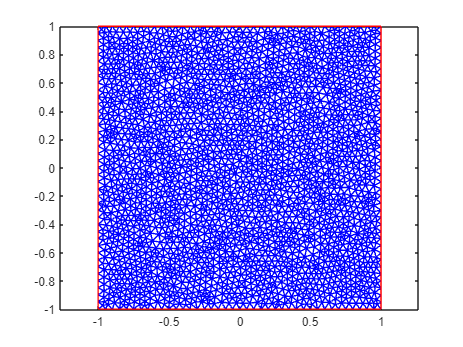

x=nodos(:,1);
y=nodos(:,2);
nn=size(nodos,1);
[p,e,t]=initmesh('squareR','hmax',h);
pdemesh(p,e,t)

Gaficamos la solución

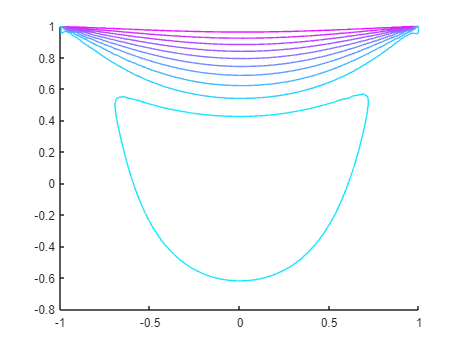

pdecont(nodos',elem',uh(1:nn))

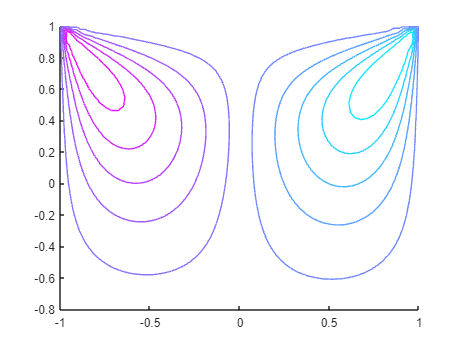

pdecont(nodos',elem',uh(nn+1:2*nn))

campo de velocidades

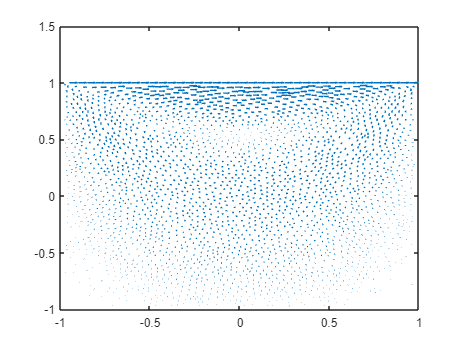

quiver(x,y,uh(1:nn),uh(nn+1:2*nn))